# Procedimiento para cálculo y gráfica de campos vectoriales

## Por: Sergio Abraham Botina Josa

`Displacement Current Density. A magnetic flux density, `$\vec{B}= \hat{y}0.1\cdot (\cos{100t})(\cos{5z})$ `[T]`` exists in a linear, isotropic,homogeneous material characterized by `$\epsilon$` and `$\mu$`. Find the displacement current density in the material if there are nosource charges or current densities in the material.`

`Densidad de corriente de desplazamiento. Existe una densidad de flujo magnético,`$\vec{B}= \hat{y}0.1\cdot (\cos{100t})(\cos{5z})$ `[T]`` en un material lineal, isotrópico y homogéneo caracterizado por `$\epsilon$` y `$\mu$ `Encuentre la densidad de corriente de desplazamiento en el material si no hay cargas de fuente o densidades de corriente en el material. `

#### `Solución:`


$$$$\vec{B}= \hat{y}0.1\cdot (\cos{100t})(\cos{5z})$$

$$\vec{H}=\frac{\vec{B}}{\mu}$$

$$\nabla\times\vec{H}=\vec{J}+\frac{\partial \vec{D}}{\partial t} $$

$$\vec{J}=0$$

$$\frac{\partial \vec{D}}{\partial t}=\nabla \times \vec{H}$$

$$\nabla \times \vec{H}=\nabla \times \left(\frac{1}{\mu}\hat{y}0.1\cdot (\cos{100t})(\cos{5z})\right)$$

$$\nabla \times \vec{H}=\frac{1}{\mu}(\sin(5z)\cos(100t))\hat{x}$$$$


t = 0;
mu = 0.1;
syms x y z;
B_field =[0,0.1*cos(100*t)*cos(5*z),0];
H_field = B_field/mu

$$H\_field = \left(\begin{array}{ccc} 0 & \cos\left(5\,z\right) & 0 \end{array}\right)$$

D_density= curl(H_field,[x,y,z])

$$D\_density = \left(\begin{array}{c} 5\,\sin\left(5\,z\right)\\ 0\\ 0 \end{array}\right)$$

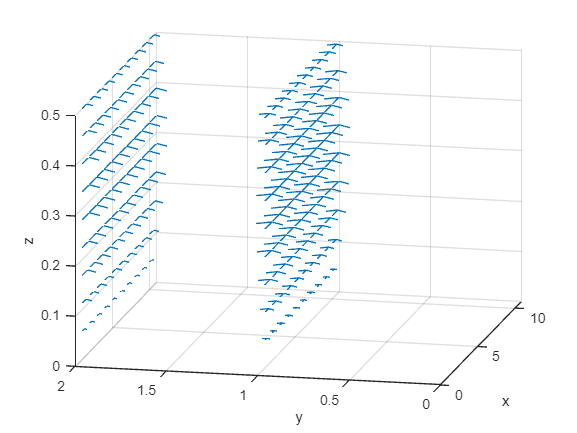

[x,y,z] = meshgrid(linspace(0,0.5,10), linspace(0,2,100), linspace(0,0.5,10));
% We now define our 3 vector−field functions
P = 0*x+5*sin(5*z)+0*z;
Q = 0*x+0*y+0*z;
R = 0*x+0*y+0*z;
% Plot the 3D vector field with quiver3
figure(2)
quiver3(z,P,Q,R)
ylim([0,2])
xlabel('x')
ylabel('y')
zlabel('z')